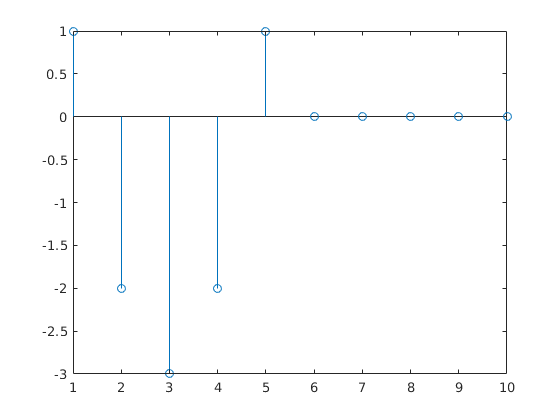

% Task 4
load Ex7_Task4.mat
X=fft(x);
Y=fft(y);
H=Y./X;
h=ifft(H);
h1=h(1:10);
n=1:10;
stem(h1)

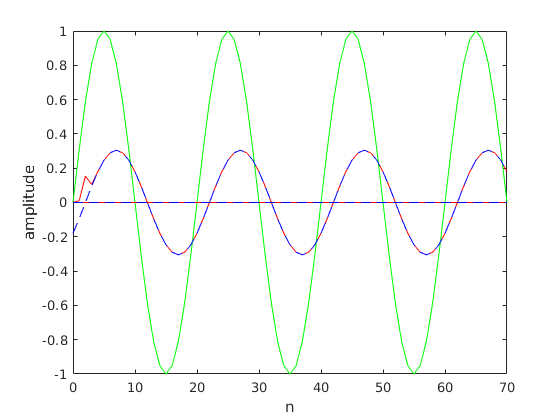

% Task 5
clear all
n=(0:70);
u = [zeros(1,7),ones(1,64)];
x=(sin(0.05*2*pi.*n))'.*u;
a = [1];
b = [0.0349 0.4302 -0.5698 0.4302 0.0349];
y = filter(b,a,x);
y_estimated=(sin(0.05*2*pi.*n-0.6283))'.*u*0.3050;
plot(n,x,'g');
hold on;
plot(n,y,'r');
plot(n,y_estimated,'b--')
xlabel('n');
ylabel('amplitude');
hold off